# Using ode45 on a system with a parameter.


$$$$x'=-x+az$$
$$y'=-y+2z$$
$$z'=x^2-2z$$$$


syms t x a
g = @(t,x,a)[-x(1)+a*x(3);
             -x(2)+2*x(3);
             x(1)^2-2*x(3)];
for a = 0:2
[t,xp] = ode45(@(t,x) g(t,x,a),[0 1.5],[1 1/2 3]);
figure
plot(t,xp(:,2))
title(['y(t) for a=',num2str(a)'])
end

# Main

## Loading paras

T = readtable('/Users/chentianchi/Desktop/code/circuit design/database/para_s4.csv');
% strcmp('AmeR',T(1,:).repressor{:})

row_names = strcat(T.repressor, '_', T.RBS)

row_names = 20×1 cell array
    {'AmeR_F1'  }
    {'AmeR_A1'  }
    {'BetI_E1'  }
    {'BM3R1_B1' }
    {'BM3R1_B2' }
    {'BM3R1_B3' }
    {'HlyIIR_H1'}
    {'IcaRA_I1' }
    {'LitR_l1'  }
    {'LmrA_N1'  }
    {'PhIF_P1'  }
    {'PhIF_P2'  }
    {'PhIF_P3'  }
    {'PsrA_R1'  }
    {'QacR_Q1'  }
    {'QacR_Q2'  }
    {'SrpR_S1'  }
    {'SrpR_S2'  }
    {'SrpR_S3'  }
    {'SrpR_S4'  }


T.Properties.RowNames = row_names

T = 20×6 table
                 repressor    RBS     Y_min    Y_max     K       n 
                 _________    ____    _____    _____    ____    ___

    AmeR_F1      'AmeR'       'F1'      0.2     3.8     0.09    1.4
    AmeR_A1      'AmeR'       'A1'     0.06     3.8     0.07    1.6
    BetI_E1      'BetI'       'E1'     0.07     3.8     0.41    2.4
    BM3R1_B1     'BM3R1'      'B1'    0.004     0.5     0.04    3.4
    BM3R1_B2     'BM3R1'      'B2'    0.005     0.5     0.15    2.9
    BM3R1_B3     'BM3R1'      'B3'     0.01     0.8     0.26    3.4
    HlyIIR_H1    'HlyIIR'     'H1'     0.07     2.5     0.19    2.6
    IcaRA_I1     'IcaRA'      'I



para_name = {'Y_min','Y_max','K','n'}

para_name = 1×4 cell array
    {'Y_min'}    {'Y_max'}    {'K'}    {'n'}


HlyIIR = table2struct(T("HlyIIR_H1",para_name))

HlyIIR = struct with fields:
    Y_min: 0.0700
    Y_max: 2.5000
        K: 0.1900
        n: 2.6000


PhIF   = table2struct(T("PhIF_P1",para_name))

PhIF = struct with fields:
    Y_min: 0.0100
    Y_max: 3.9000
        K: 0.0300
        n: 4


PsrA   = table2struct(T("PsrA_R1",para_name))

PsrA = struct with fields:
    Y_min: 0.2000
    Y_max: 5.9000
        K: 0.1900
        n: 1.8000


LmrA   = table2struct(T("LmrA_N1",para_name))

LmrA = struct with fields:
    Y_min: 0.2000
    Y_max: 2.2000
        K: 0.1800
        n: 2.1000


SrpR   = table2struct(T("SrpR_S4",para_name))

SrpR = struct with fields:
    Y_min: 0.0070
    Y_max: 2.1000
        K: 0.1000
        n: 2.8000


BM3R1  = table2struct(T("BM3R1_B3",para_name))

BM3R1 = struct with fields:
    Y_min: 0.0100
    Y_max: 0.8000
        K: 0.2600
        n: 3.4000


BetI   = table2struct(T("BetI_E1",para_name))

BetI = struct with fields:
    Y_min: 0.0700
    Y_max: 3.8000
        K: 0.4100
        n: 2.4000


## ODE

xi = 0.025

xi = 0.0250

gma =0.025

gma = 0.0250


syms t x p
plasmid = @(t,x,p)[xi*(HlyIIR.Y_min + (HlyIIR.Y_max - HlyIIR.Y_min)*HlyIIR.K^HlyIIR.n/(HlyIIR.K^HlyIIR.n + (x(7) + p)^HlyIIR.n)) - gma*(x(1));
                   xi*(LmrA.Y_min + (LmrA.Y_max - LmrA.Y_min)*LmrA.K^LmrA.n/(LmrA.K^LmrA.n + (x(1) + p)^LmrA.n)) - gma*(x(2));
                   xi*(SrpR.Y_min + (SrpR.Y_max - SrpR.Y_min)*SrpR.K^SrpR.n/(SrpR.K^SrpR.n + (x(1) + x(7))^SrpR.n)) - gma*(x(3))
                   xi*(BM3R1.Y_min + (BM3R1.Y_max - BM3R1.Y_min)*BM3R1.K^BM3R1.n/(BM3R1.K^BM3R1.n + (x(2) + x(3))^BM3R1.n)) - gma*(x(4))
                   xi*(PhIF.Y_min + (PhIF.Y_max - PhIF.Y_min)*PhIF.K^PhIF.n/(PhIF.K^PhIF.n + (x(4))^PhIF.n)) - gma*(x(5))
                   xi*(PsrA.Y_min + (PsrA.Y_max - PsrA.Y_min)*PsrA.K^PsrA.n/(PsrA.K^PsrA.n + (x(5) + x(7))^PsrA.n)) - gma*(x(6))
                   xi*(BetI.Y_min + (BetI.Y_max - BetI.Y_min)*BetI.K^BetI.n/(BetI.K^BetI.n + (x(4) + x(6))^BetI.n)) - gma*(x(7))];



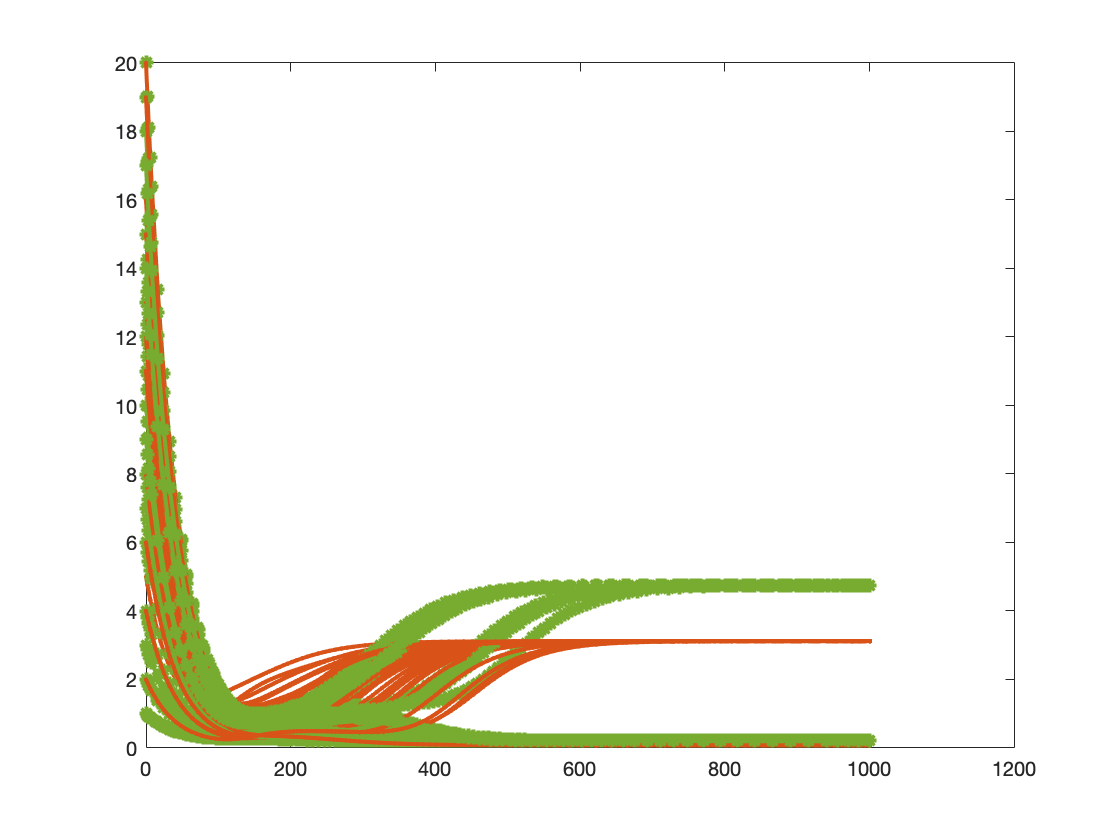

p = 0

u0 =     13    20    12    17    10    11     4


p = 0

u0 =     13    20    11    10    16     2    18


p = 0

u0 =      1    11    14    12    10     7    13


p = 0

u0 =     19    14    19     2    11     3    11


p = 0

u0 =     14     3    16     8    18     7     2


p = 0

u0 =      5     2    20     1     3     1     5


p = 0

u0 =      1    13    11     5     4     2     8


p = 0

u0 =      1    13    10     7    15    17     6


p = 0

u0 =     11     9     7    17    20    13     4


p = 0

u0 =      3    12     7     6    12     4    14


p = 0

u0 =      2     1     6     2    19    17     8


p = 0

u0 =      4     9     9    15     9    20    19


p = 0

u0 =     20     7     6    18     5     3    11


p = 0

u0 =     19     9     5     2    19    13     8


p = 0

u0 =     14    16     7    14     5    20    15


p = 0

u0 =      4     9    13    19    11    13    14


p = 0

u0 =     19     4     9     7    14    18    10


p = 0

u0 =     17     7    11     8    18    14    17


p = 0

u0 =      3     6    16     5     1     9    19


p = 0

u0 =      6    12     8     1    11    17     6


p = 0

u0 =      1     5    14     7    14     1    15


p = 0

u0 =      8     1     9    15    19    20    20


p = 0

u0 =     18    18    17    12     9     3    14


p = 0

u0 =     18     6    17     2     8     6     4


p = 0

u0 =     13     7    20    10    15     1    13


p = 0

u0 =     12    17    14    18    19     4     4


p = 0

u0 =     16     2     8     6    15     3    16


p = 0

u0 =     16    11     6     2    13     1     2


p = 0

u0 =      3    10    14    18    10     1     7


p = 0

u0 =     13    16     6    10    17    12    11


p = 0

u0 =      7     9    16     7    10     8    14


p = 0

u0 =     12    14    10     8    10     2     9


p = 0

u0 =     20    16    15    16    16    17    16


p = 0

u0 =     20     3     8    10     6     1    20


p = 0

u0 =     15     3     3    15     8     2     9


p = 0

u0 =      3    16    19     1    14    14     6


p = 0

u0 =     17     6     1     2    16    15    16


p = 0

u0 =     13    17     1     9     5    10    18


p = 0

u0 =      6    12     1     4    17     4    17


p = 0

u0 =      7    14     2    15    10    19     6


p = 0

u0 =      8     3    20     9     2    15    11


p = 0

u0 =      7    16    17     6    11     9     4


p = 0

u0 =     13    19     3    18    12     9     4


p = 0

u0 =      5     9    11     8    16    18    15


p = 0

u0 =      9    13    13     3    10     7    12


p = 0

u0 =     19     9     1    19    19     8     6


p = 0

u0 =     16    11    12    14     2    18    19


p = 0

u0 =      2    17    19     1    11    14     8


p = 0

u0 =     13    16    12    13     6    17     9


p = 0

u0 =     13    17     6     9    12     9     2



figure             
for rd = 1:50
    p=0
    u0= randi([1 20],1,7)
    [t,xp] = ode45(@(t,x) plasmid(t,x,p),[0 1000.5],u0);
%     figure
%     plot(t,xp(:,6:7),'LineWidth',2)
    plot(t,xp(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
%     legend('x6')
    hold on
    plot(t,xp(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')

%     legend('x7')
    title()
end

## Two attractors

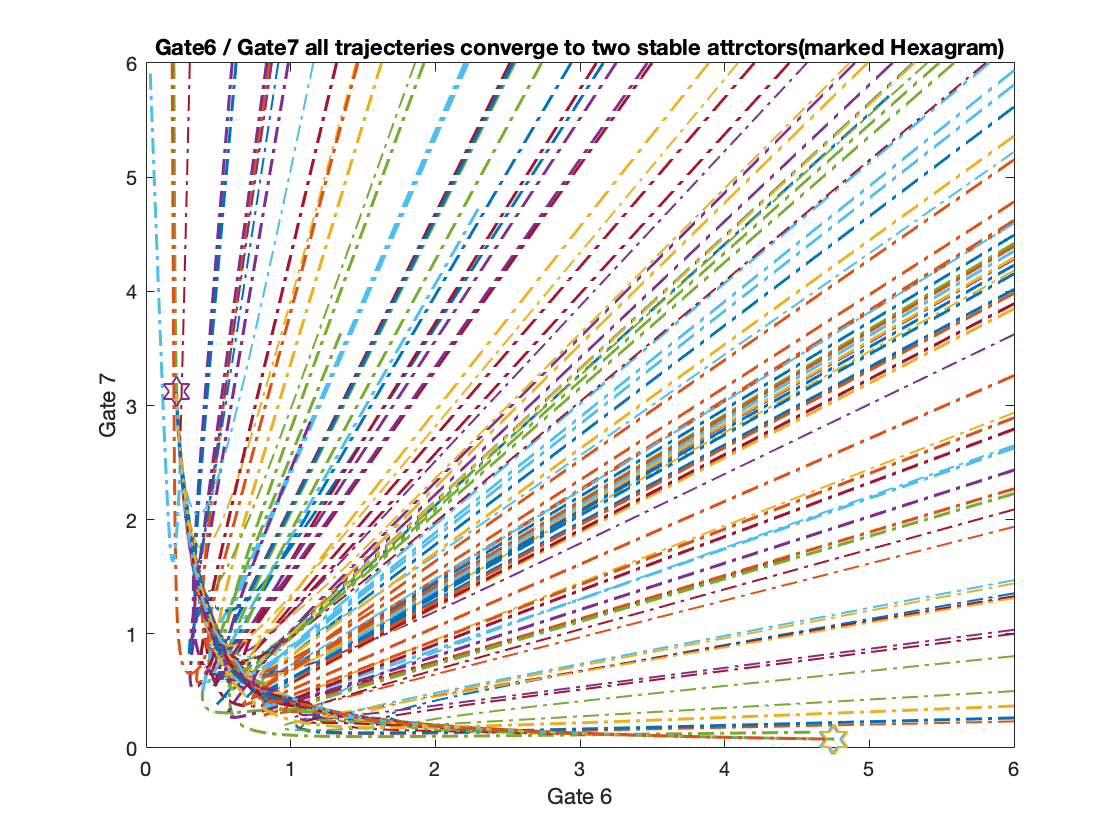

figure           
for rd = 1:100
     p=0;
%     u0= rand([1 20],1,7)
    u0 = [rand(1,7)*20];% rand(1)+4 rand(1)*0.25]
    [t,xp] = ode45(@(t,x) plasmid(t,x,p),[0 1000.5],u0);
%     figure
    plot(xp(:,6),xp(:,7),'-.','LineWidth',1);
    hold on;
    plot(xp(end,6),xp(end,7),'Marker' ,'h','MarkerSize',15)
    
end
axis([0 6 0 6])
xlabel('Gate 6')
ylabel('Gate 7')
title('Gate6 / Gate7 all trajecteries converge to two stable attrctors(marked Hexagram)')

## random seed

s = rng

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


## Sequential simulation

- Simulation the system untill it goes to steady state

p=0

p = 0

rng(s)
u0= randi([1 20],1,7)

u0 =      3    16     6    13    20     9    14


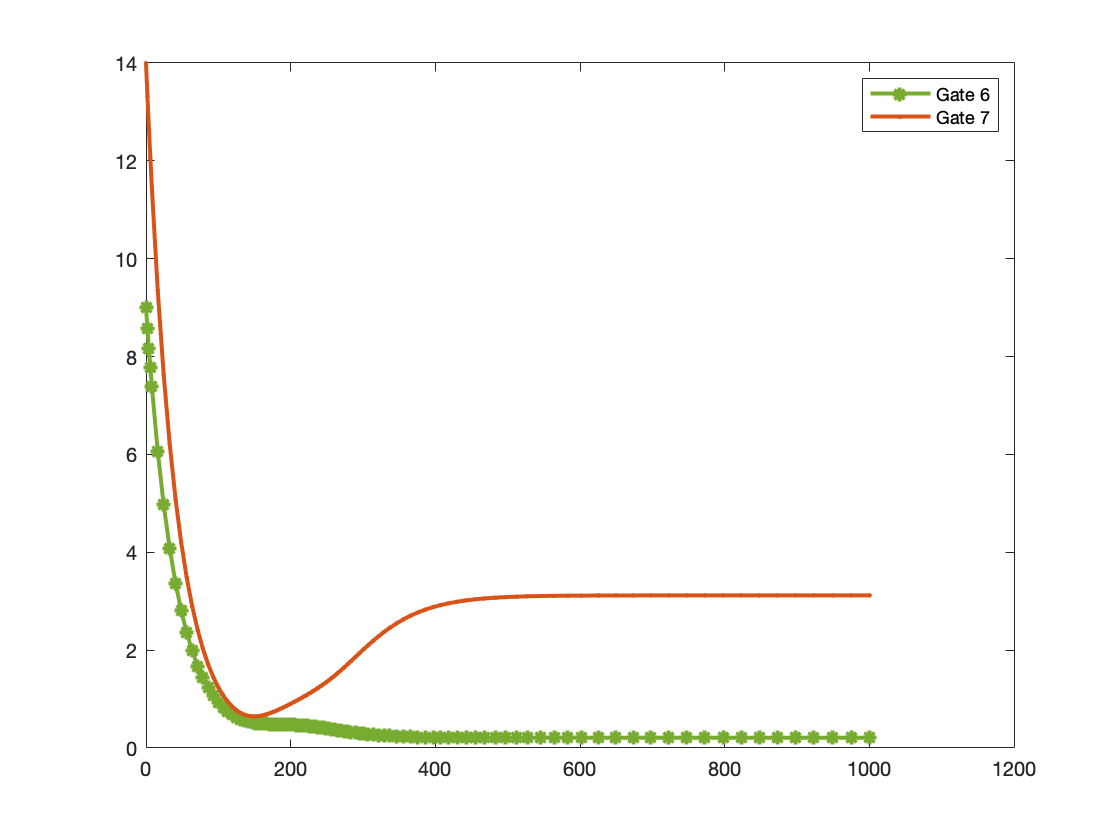

[t,xp] = ode45(@(t,x) plasmid(t,x,p),[0 1000.5],u0);
figure
plot(t,xp(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t,xp(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')


p = 20

p = 20

u0_t1 = xp(end,:)

u0_t1 =     0.0717    1.9473    0.0071    0.0108    3.8351    0.2087    3.1189


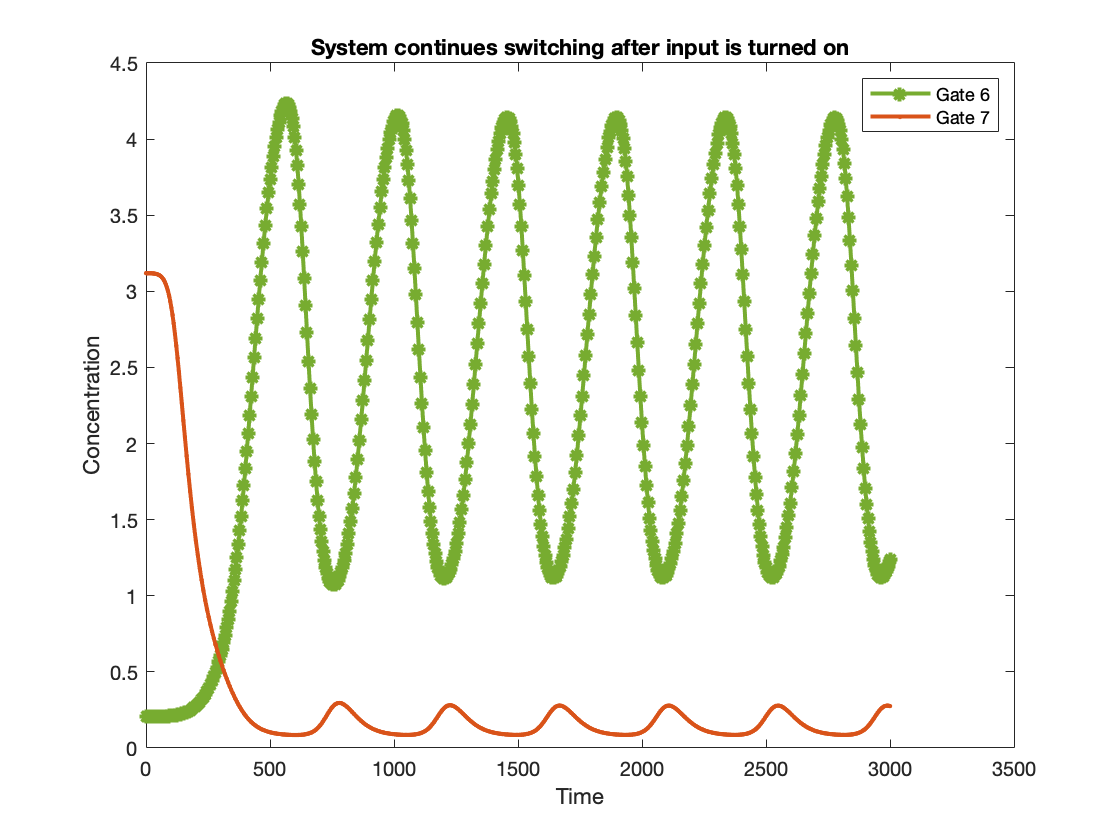

[t,xp] = ode45(@(t,x) plasmid(t,x,p),[0 3000.5],u0_t1);
figure
plot(t,xp(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t,xp(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
xlabel('Time')
ylabel('Concentration')
title('System continues switching after input is turned on')

## Find the lb and ub of the P inpluse and the min time to wait for the next signal

% Find the local minimum index
locs2 =  find(islocalmin(xp(:,6)));
ind_min1 = locs2(2,1)

ind_min1 = 136


% Test the time starting from ti =1 to ti = first local min
t_wait = [];
for ti = 1: ind_min1
    p = 0
    u0_t11 = xp(ti,:)
    fprintf('The duration of P is %d:', t(ti));
    [tt,xp1] = ode45(@(t,x) plasmid(t,x,p),[0 3000.5],u0_t11);
    % How much time to wait until the system become statble again
    [~,locs]  =findpeaks(xp1(:,6));
    stable_t_ind = locs(1)
    if t(ti) > 306 & t(ti) < 703% lb ; ub
        t_wait = [t_wait, t(stable_t_ind)];
    end
    
%     figure
%     plot(tt,xp1(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
%     hold on
%     plot(tt,xp1(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
%     legend('Gate 6','Gate 7')
end

p = 0

u0_t11 =     0.0717    1.9473    0.0071    0.0108    3.8351    0.2087    3.1189


The duration of P is 0:

stable_t_ind = 5

p = 0

u0_t11 =     0.0716    1.8521    0.0071    0.0108    3.8351    0.2087    3.1189


The duration of P is 2.239653e+00:

stable_t_ind = 3

p = 0

u0_t11 =     0.0715    1.7622    0.0071    0.0108    3.8350    0.2087    3.1189


The duration of P is 4.479307e+00:

stable_t_ind = 3

p = 0

u0_t11 =     0.0714    1.6771    0.0071    0.0109    3.8350    0.2087    3.1189


The duration of P is 6.718960e+00:

stable_t_ind = 3

p = 0

u0_t11 =     0.0713    1.5967    0.0071    0.0109    3.8349    0.2087    3.1189


The duration of P is 8.958613e+00:

stable_t_ind = 12

p = 0

u0_t11 =     0.0712    1.4570    0.0071    0.0110    3.8346    0.2087    3.1188


The duration of P is 1.317286e+01:

stable_t_ind = 14

p = 0

u0_t11 =     0.0711    1.3313    0.0071    0.0112    3.8341    0.2087    3.1187


The duration of P is 1.738711e+01:

stable_t_ind = 15

p = 0

u0_t11 =     0.0710    1.2182    0.0071    0.0114    3.8331    0.2087    3.1185


The duration of P is 2.160136e+01:

stable_t_ind = 15

p = 0

u0_t11 =     0.0709    1.1164    0.0071    0.0117    3.8314    0.2087    3.1181


The duration of P is 2.581561e+01:

stable_t_ind = 16

p = 0

u0_t11 =     0.0708    1.0248    0.0071    0.0122    3.8286    0.2087    3.1175


The duration of P is 3.002986e+01:

stable_t_ind = 16

p = 0

u0_t11 =     0.0707    0.9423    0.0071    0.0128    3.8244    0.2087    3.1166


The duration of P is 3.424411e+01:

stable_t_ind = 17

p = 0

u0_t11 =     0.0706    0.8681    0.0071    0.0136    3.8181    0.2087    3.1154


The duration of P is 3.845837e+01:

stable_t_ind = 17

p = 0

u0_t11 =     0.0706    0.8013    0.0071    0.0147    3.8080    0.2087    3.1137


The duration of P is 4.267262e+01:

stable_t_ind = 17

p = 0

u0_t11 =     0.0705    0.7402    0.0071    0.0161    3.7910    0.2087    3.1114


The duration of P is 4.695692e+01:

stable_t_ind = 17

p = 0

u0_t11 =     0.0705    0.6854    0.0071    0.0180    3.7645    0.2088    3.1083


The duration of P is 5.124122e+01:

stable_t_ind = 18

p = 0

u0_t11 =     0.0704    0.6361    0.0071    0.0203    3.7233    0.2088    3.1042


The duration of P is 5.552553e+01:

stable_t_ind = 18

p = 0

u0_t11 =     0.0704    0.5918    0.0071    0.0232    3.6568    0.2088    3.0988


The duration of P is 5.980983e+01:

stable_t_ind = 19

p = 0

u0_t11 =     0.0703    0.5540    0.0071    0.0267    3.5595    0.2089    3.0923


The duration of P is 6.387383e+01:

stable_t_ind = 19

p = 0

u0_t11 =     0.0703    0.5198    0.0071    0.0308    3.4212    0.2089    3.0840


The duration of P is 6.793784e+01:

stable_t_ind = 19

p = 0

u0_t11 =     0.0703    0.4889    0.0071    0.0358    3.2409    0.2091    3.0738


The duration of P is 7.200185e+01:

stable_t_ind = 19

p = 0

u0_t11 =     0.0703    0.4610    0.0071    0.0417    3.0283    0.2092    3.0611


The duration of P is 7.606585e+01:

stable_t_ind = 20

p = 0

u0_t11 =     0.0702    0.4348    0.0071    0.0488    2.7894    0.2094    3.0447


The duration of P is 8.029892e+01:

stable_t_ind = 20

p = 0

u0_t11 =     0.0702    0.4112    0.0071    0.0571    2.5472    0.2097    3.0249


The duration of P is 8.453199e+01:

stable_t_ind = 20

p = 0

u0_t11 =     0.0702    0.3900    0.0071    0.0665    2.3129    0.2101    3.0011


The duration of P is 8.876506e+01:

stable_t_ind = 21

p = 0

u0_t11 =     0.0702    0.3710    0.0071    0.0772    2.0933    0.2106    2.9728


The duration of P is 9.299812e+01:

stable_t_ind = 21

p = 0

u0_t11 =     0.0702    0.3523    0.0071    0.0900    1.8726    0.2112    2.9362


The duration of P is 9.762989e+01:

stable_t_ind = 22

p = 0

u0_t11 =     0.0701    0.3356    0.0071    0.1042    1.6728    0.2119    2.8935


The duration of P is 1.022616e+02:

stable_t_ind = 22

p = 0

u0_t11 =     0.0701    0.3208    0.0071    0.1196    1.4931    0.2128    2.8447


The duration of P is 1.068934e+02:

stable_t_ind = 24

p = 0

u0_t11 =     0.0701    0.3076    0.0071    0.1359    1.3323    0.2137    2.7896


The duration of P is 1.115252e+02:

stable_t_ind = 25

p = 0

u0_t11 =     0.0701    0.2944    0.0071    0.1554    1.1708    0.2149    2.7200


The duration of P is 1.167656e+02:

stable_t_ind = 26

p = 0

u0_t11 =     0.0701    0.2828    0.0072    0.1757    1.0287    0.2163    2.6434


The duration of P is 1.220060e+02:

stable_t_ind = 27

p = 0

u0_t11 =     0.0701    0.2727    0.0072    0.1964    0.9040    0.2178    2.5611


The duration of P is 1.272464e+02:

stable_t_ind = 27

p = 0

u0_t11 =     0.0701    0.2638    0.0072    0.2174    0.7944    0.2196    2.4739


The duration of P is 1.324868e+02:

stable_t_ind = 27

p = 0

u0_t11 =     0.0701    0.2548    0.0072    0.2415    0.6844    0.2219    2.3687


The duration of P is 1.385387e+02:

stable_t_ind = 28

p = 0

u0_t11 =     0.0701    0.2471    0.0072    0.2651    0.5898    0.2245    2.2608


The duration of P is 1.445906e+02:

stable_t_ind = 27

p = 0

u0_t11 =     0.0700    0.2405    0.0072    0.2882    0.5085    0.2276    2.1521


The duration of P is 1.506425e+02:

stable_t_ind = 27

p = 0

u0_t11 =     0.0700    0.2349    0.0072    0.3103    0.4386    0.2310    2.0442


The duration of P is 1.566944e+02:

stable_t_ind = 26

p = 0

u0_t11 =     0.0700    0.2292    0.0073    0.3348    0.3687    0.2356    1.9197


The duration of P is 1.638116e+02:

stable_t_ind = 25

p = 0

u0_t11 =     0.0700    0.2244    0.0073    0.3576    0.3103    0.2410    1.7998


The duration of P is 1.709289e+02:

stable_t_ind = 24

p = 0

u0_t11 =     0.0700    0.2205    0.0074    0.3787    0.2614    0.2473    1.6857


The duration of P is 1.780461e+02:

stable_t_ind = 25

p = 0

u0_t11 =     0.0700    0.2172    0.0074    0.3981    0.2205    0.2546    1.5780


The duration of P is 1.851633e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2141    0.0075    0.4174    0.1825    0.2638    1.4654


The duration of P is 1.931104e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2116    0.0076    0.4347    0.1514    0.2745    1.3612


The duration of P is 2.010575e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2095    0.0078    0.4500    0.1260    0.2870    1.2656


The duration of P is 2.090046e+02:

stable_t_ind = 22

p = 0

u0_t11 =     0.0700    0.2078    0.0079    0.4634    0.1051    0.3013    1.1777


The duration of P is 2.169517e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2065    0.0081    0.4741    0.0894    0.3159    1.1035


The duration of P is 2.241952e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2055    0.0083    0.4835    0.0762    0.3322    1.0348


The duration of P is 2.314387e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2046    0.0085    0.4917    0.0653    0.3505    0.9713


The duration of P is 2.386822e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2038    0.0088    0.4988    0.0561    0.3709    0.9123


The duration of P is 2.459257e+02:

stable_t_ind = 24

p = 0

u0_t11 =     0.0700    0.2032    0.0091    0.5045    0.0489    0.3920    0.8598


The duration of P is 2.528026e+02:

stable_t_ind = 25

p = 0

u0_t11 =     0.0700    0.2027    0.0095    0.5095    0.0427    0.4153    0.8106


The duration of P is 2.596794e+02:

stable_t_ind = 26

p = 0

u0_t11 =     0.0700    0.2023    0.0099    0.5137    0.0376    0.4410    0.7644


The duration of P is 2.665563e+02:

stable_t_ind = 28

p = 0

u0_t11 =     0.0700    0.2020    0.0104    0.5173    0.0332    0.4692    0.7209


The duration of P is 2.734332e+02:

stable_t_ind = 29

p = 0

u0_t11 =     0.0700    0.2017    0.0109    0.5201    0.0296    0.4990    0.6806


The duration of P is 2.801431e+02:

stable_t_ind = 31

p = 0

u0_t11 =     0.0700    0.2014    0.0115    0.5223    0.0266    0.5316    0.6424


The duration of P is 2.868530e+02:

stable_t_ind = 33

p = 0

u0_t11 =     0.0700    0.2012    0.0123    0.5240    0.0241    0.5675    0.6061


The duration of P is 2.935629e+02:

stable_t_ind = 35

p = 0

u0_t11 =     0.0700    0.2011    0.0131    0.5252    0.0219    0.6067    0.5715


The duration of P is 3.002728e+02:

stable_t_ind = 36

p = 0

u0_t11 =     0.0700    0.2009    0.0140    0.5258    0.0202    0.6466    0.5404


The duration of P is 3.065727e+02:

stable_t_ind = 37

p = 0

u0_t11 =     0.0700    0.2008    0.0150    0.5260    0.0187    0.6901    0.5106


The duration of P is 3.128726e+02:

stable_t_ind = 93

p = 0

u0_t11 =     0.0700    0.2007    0.0162    0.5258    0.0174    0.7375    0.4821


The duration of P is 3.191725e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2006    0.0176    0.5251    0.0164    0.7892    0.4547


The duration of P is 3.254724e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2005    0.0191    0.5240    0.0155    0.8421    0.4298


The duration of P is 3.314466e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2005    0.0208    0.5225    0.0147    0.8995    0.4059


The duration of P is 3.374208e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2004    0.0228    0.5205    0.0141    0.9618    0.3831


The duration of P is 3.433951e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2004    0.0251    0.5179    0.0135    1.0292    0.3612


The duration of P is 3.493693e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2003    0.0276    0.5149    0.0131    1.0988    0.3411


The duration of P is 3.551169e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2003    0.0304    0.5113    0.0126    1.1735    0.3218


The duration of P is 3.608646e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2003    0.0337    0.5070    0.0123    1.2538    0.3036


The duration of P is 3.666123e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2003    0.0374    0.5021    0.0120    1.3394    0.2862


The duration of P is 3.723599e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2002    0.0416    0.4964    0.0117    1.4287    0.2701


The duration of P is 3.780143e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2002    0.0463    0.4899    0.0115    1.5231    0.2548


The duration of P is 3.836687e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2002    0.0516    0.4825    0.0113    1.6226    0.2405


The duration of P is 3.893231e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2002    0.0575    0.4741    0.0112    1.7268    0.2270


The duration of P is 3.949775e+02:

stable_t_ind = 61

p = 0

u0_t11 =     0.0700    0.2002    0.0642    0.4645    0.0110    1.8363    0.2143


The duration of P is 4.006997e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2002    0.0716    0.4538    0.0109    1.9496    0.2024


The duration of P is 4.064219e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2002    0.0798    0.4420    0.0108    2.0662    0.1915


The duration of P is 4.121440e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2002    0.0888    0.4291    0.0107    2.1852    0.1813


The duration of P is 4.178662e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2001    0.0990    0.4145    0.0106    2.3106    0.1716


The duration of P is 4.238199e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2001    0.1100    0.3987    0.0105    2.4368    0.1627


The duration of P is 4.297737e+02:

stable_t_ind = 65

p = 0

u0_t11 =     0.0700    0.2001    0.1218    0.3821    0.0105    2.5631    0.1546


The duration of P is 4.357274e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.1344    0.3647    0.0104    2.6884    0.1472


The duration of P is 4.416811e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.1485    0.3455    0.0104    2.8196    0.1401


The duration of P is 4.480199e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.1632    0.3259    0.0104    2.9477    0.1337


The duration of P is 4.543588e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.1785    0.3062    0.0104    3.0722    0.1279


The duration of P is 4.606976e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.1943    0.2867    0.0104    3.1922    0.1227


The duration of P is 4.670365e+02:

stable_t_ind = 69

p = 0

u0_t11 =     0.0700    0.2001    0.2116    0.2659    0.0104    3.3163    0.1177


The duration of P is 4.739168e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.2291    0.2458    0.0105    3.4339    0.1133


The duration of P is 4.807972e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.2466    0.2266    0.0105    3.5446    0.1094


The duration of P is 4.876776e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.2640    0.2085    0.0107    3.6480    0.1060


The duration of P is 4.945580e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.2788    0.1937    0.0109    3.7320    0.1033


The duration of P is 5.005654e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.2933    0.1798    0.0111    3.8103    0.1009


The duration of P is 5.065727e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.3074    0.1668    0.0114    3.8827    0.0987


The duration of P is 5.125801e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.3211    0.1548    0.0119    3.9493    0.0968


The duration of P is 5.185875e+02:

stable_t_ind = 73

p = 0

u0_t11 =     0.0700    0.2001    0.3342    0.1437    0.0125    4.0097    0.0951


The duration of P is 5.245949e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.3467    0.1335    0.0134    4.0641    0.0936


The duration of P is 5.306022e+02:

stable_t_ind = 24

p = 0

u0_t11 =     0.0700    0.2001    0.3587    0.1241    0.0145    4.1121    0.0922


The duration of P is 5.366096e+02:

stable_t_ind = 22

p = 0

u0_t11 =     0.0700    0.2001    0.3700    0.1156    0.0160    4.1534    0.0910


The duration of P is 5.426170e+02:

stable_t_ind = 20

p = 0

u0_t11 =     0.0700    0.2001    0.3797    0.1085    0.0178    4.1841    0.0900


The duration of P is 5.480423e+02:

stable_t_ind = 18

p = 0

u0_t11 =     0.0700    0.2001    0.3889    0.1020    0.0201    4.2085    0.0892


The duration of P is 5.534676e+02:

stable_t_ind = 16

p = 0

u0_t11 =     0.0700    0.2001    0.3976    0.0961    0.0229    4.2258    0.0884


The duration of P is 5.588928e+02:

stable_t_ind = 14

p = 0

u0_t11 =     0.0700    0.2001    0.4057    0.0906    0.0266    4.2350    0.0877


The duration of P is 5.643181e+02:

stable_t_ind = 10

p = 0

u0_t11 =     0.0700    0.2001    0.4128    0.0859    0.0307    4.2353    0.0872


The duration of P is 5.693777e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.4195    0.0817    0.0357    4.2267    0.0867


The duration of P is 5.744372e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.4257    0.0777    0.0418    4.2084    0.0863


The duration of P is 5.794968e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.4315    0.0741    0.0491    4.1790    0.0859


The duration of P is 5.845564e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.4368    0.0708    0.0578    4.1370    0.0857


The duration of P is 5.896417e+02:

stable_t_ind = 77

p = 0

u0_t11 =     0.0700    0.2001    0.4417    0.0678    0.0679    4.0815    0.0855


The duration of P is 5.947271e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4461    0.0650    0.0797    4.0122    0.0854


The duration of P is 5.998125e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4500    0.0625    0.0932    3.9283    0.0854


The duration of P is 6.048978e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4536    0.0601    0.1093    3.8243    0.0855


The duration of P is 6.102282e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4565    0.0579    0.1274    3.7049    0.0857


The duration of P is 6.155586e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4589    0.0559    0.1477    3.5716    0.0861


The duration of P is 6.208890e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4605    0.0542    0.1699    3.4264    0.0867


The duration of P is 6.262194e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4614    0.0525    0.1958    3.2594    0.0876


The duration of P is 6.319564e+02:

stable_t_ind = 81

p = 0

u0_t11 =     0.0700    0.2001    0.4613    0.0511    0.2236    3.0850    0.0888


The duration of P is 6.376934e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4602    0.0498    0.2530    2.9070    0.0903


The duration of P is 6.434304e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4578    0.0488    0.2833    2.7288    0.0922


The duration of P is 6.491674e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4536    0.0479    0.3158    2.5414    0.0949


The duration of P is 6.553017e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4476    0.0473    0.3478    2.3605    0.0982


The duration of P is 6.614361e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4398    0.0469    0.3783    2.1888    0.1024


The duration of P is 6.675704e+02:

stable_t_ind = 85

p = 0

u0_t11 =     0.0700    0.2001    0.4297    0.0468    0.4058    2.0279    0.1075


The duration of P is 6.737048e+02:

stable_t_ind = 89

p = 0

u0_t11 =     0.0700    0.2001    0.4176    0.0470    0.4282    1.8825    0.1136


The duration of P is 6.796788e+02:

stable_t_ind = 89

p = 0

u0_t11 =     0.0700    0.2001    0.4034    0.0476    0.4453    1.7493    0.1209


The duration of P is 6.856529e+02:

stable_t_ind = 93

p = 0

u0_t11 =     0.0700    0.2001    0.3870    0.0486    0.4563    1.6287    0.1297


The duration of P is 6.916270e+02:

stable_t_ind = 97

p = 0

u0_t11 =     0.0700    0.2001    0.3688    0.0500    0.4599    1.5208    0.1398


The duration of P is 6.976010e+02:

stable_t_ind = 101

p = 0

u0_t11 =     0.0700    0.2001    0.3505    0.0518    0.4559    1.4326    0.1504


The duration of P is 7.030776e+02:

stable_t_ind = 109

p = 0

u0_t11 =     0.0700    0.2001    0.3312    0.0542    0.4451    1.3549    0.1623


The duration of P is 7.085542e+02:

stable_t_ind = 50

p = 0

u0_t11 =     0.0700    0.2001    0.3113    0.0573    0.4281    1.2876    0.1753


The duration of P is 7.140308e+02:

stable_t_ind = 46

p = 0

u0_t11 =     0.0700    0.2001    0.2910    0.0610    0.4057    1.2304    0.1892


The duration of P is 7.195074e+02:

stable_t_ind = 43

p = 0

u0_t11 =     0.0700    0.2001    0.2711    0.0656    0.3795    1.1833    0.2035


The duration of P is 7.248971e+02:

stable_t_ind = 40

p = 0

u0_t11 =     0.0700    0.2001    0.2517    0.0710    0.3506    1.1452    0.2179


The duration of P is 7.302868e+02:

stable_t_ind = 97

p = 0

u0_t11 =     0.0700    0.2001    0.2330    0.0774    0.3205    1.1158    0.2323


The duration of P is 7.356765e+02:

stable_t_ind = 39

p = 0

u0_t11 =     0.0700    0.2001    0.2152    0.0848    0.2905    1.0943    0.2460


The duration of P is 7.410663e+02:

stable_t_ind = 45

p = 0

u0_t11 =     0.0700    0.2001    0.1982    0.0934    0.2608    1.0797    0.2588


The duration of P is 7.465685e+02:

stable_t_ind = 21

p = 0

u0_t11 =     0.0700    0.2001    0.1825    0.1031    0.2329    1.0721    0.2701


The duration of P is 7.520707e+02:

stable_t_ind = 23

p = 0

u0_t11 =     0.0700    0.2001    0.1680    0.1138    0.2072    1.0712    0.2795


The duration of P is 7.575729e+02:

stable_t_ind = 81

max(t_wait)% give the min time to wait(lower bound) for the next signal within the switching range

t_wait =   156.6944  518.5875  467.0365  441.6811  417.8662  394.9775  372.3599  372.3599  349.3693  349.3693  325.4724  325.4724  325.4724  325.4724  325.4724  325.4724  349.3693  349.3693  349.3693  349.3693  349.3693  349.3693  372.3599  372.3599  372.3599  372.3599  372.3599  372.3599  394.9775  394.9775


## Now test the square wave inpulse

set P duration= 400, and t_wait = 570

% Initialize vector of the final plot
P_set = [];
sol_set =[];


% 1. make system goes to steady state
p=0

p = 0

rng(s)
u0= randi([1 20],1,7)

u0 =      3    16     6    13    20     9    14


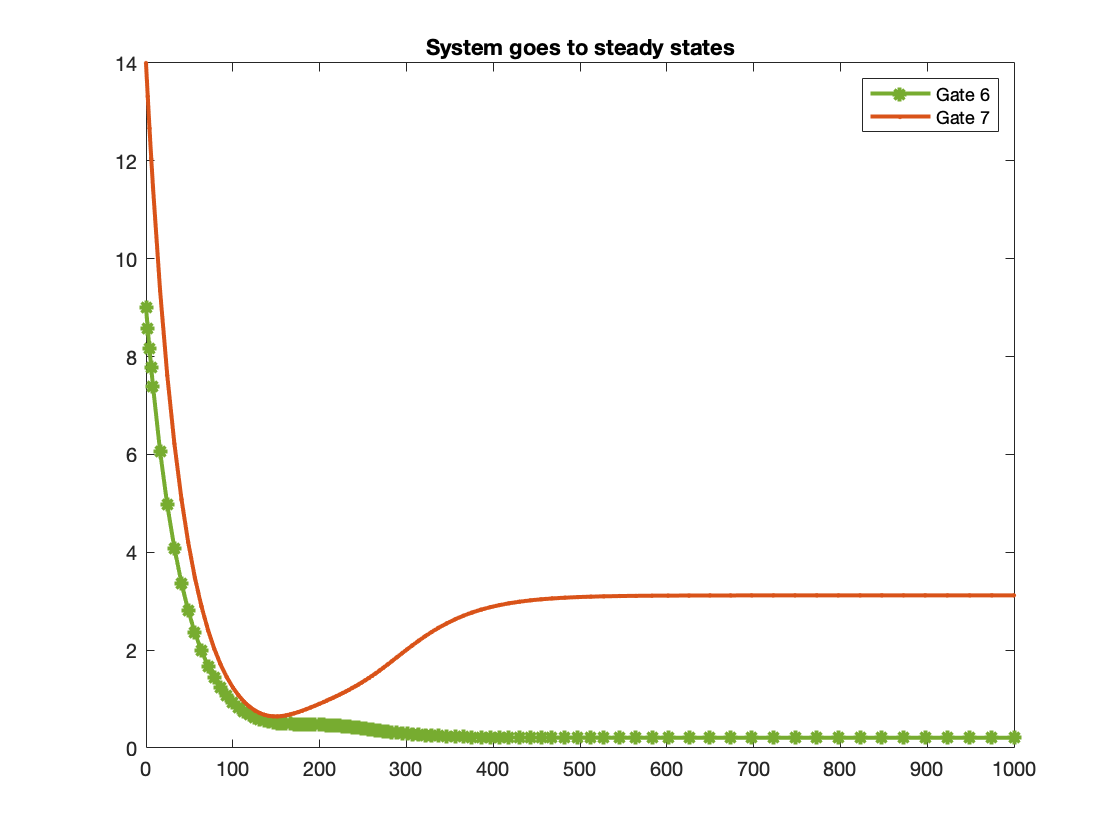

[t1,sol1] = ode45(@(t,x) plasmid(t,x,p),[0 1000],u0);
figure
plot(t1,sol1(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t1,sol1(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
title('System goes to steady states')


p1 = zeros(size(t1))

p1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% 2. add inpulse p=20 for 400s
p = 20

p = 20

u0_t1 = sol1(end,:)

u0_t1 =     0.0717    1.9473    0.0071    0.0108    3.8351    0.2087    3.1189


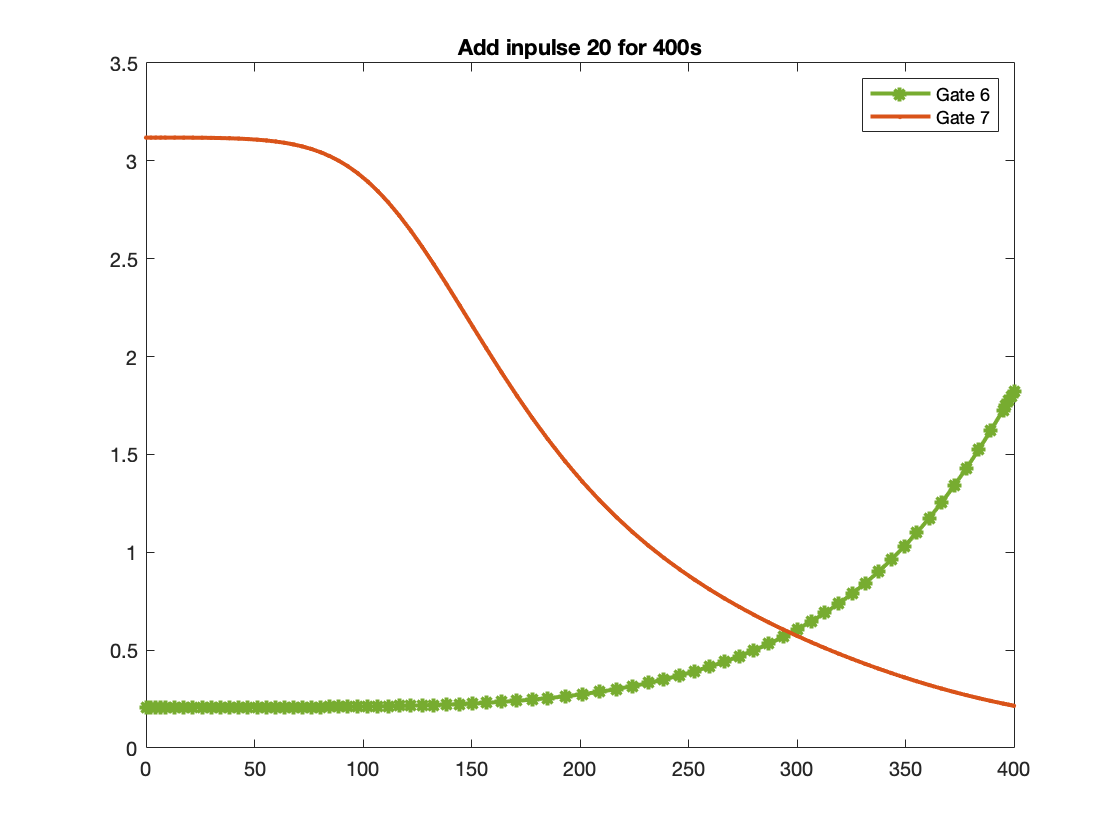

[t2,sol2] = ode45(@(t,x) plasmid(t,x,p),[0 400],u0_t1);
figure
plot(t2,sol2(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t2,sol2(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
title('Add inpulse 20 for 400s')


p2 = zeros(size(t2))+20

p2 =     20
    20
    20
    20
    20
    20
    20
    20
    20
    20



% 3. turn off p, p=0, for 570s
p = 0

p = 0

u0_t2 = sol2(end,:)

u0_t2 =     0.0700    0.2002    0.0634    0.4657    0.0110    1.8228    0.2158


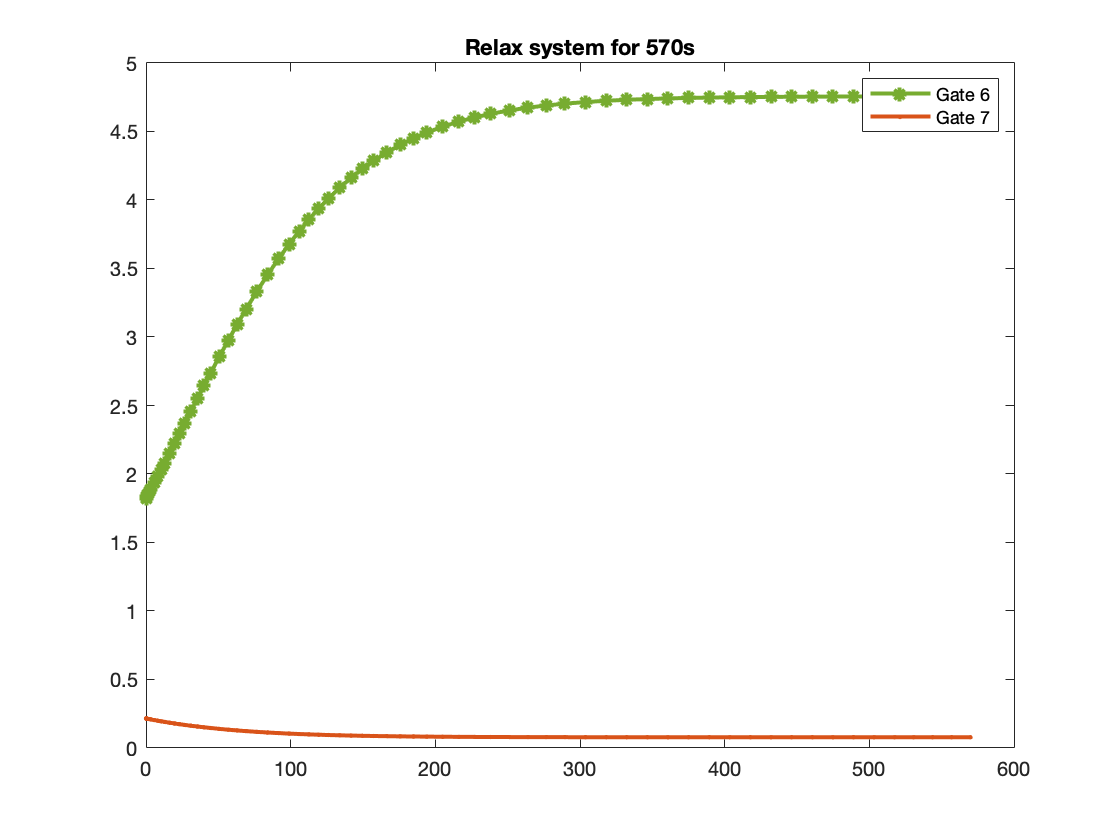

[t3,sol3] = ode45(@(t,x) plasmid(t,x,p),[0 570],u0_t2);
figure
plot(t3,sol3(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t3,sol3(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
title('Relax system for 570s')

p3 = zeros(size(t3))

p3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% % repeat 2 & 3

% 4. add inpulse p=20 for 400s
p = 20

p = 20

u0_t3 = sol3(end,:)

u0_t3 =     2.2809    0.2096    0.0073    0.5229    0.0100    4.7567    0.0781


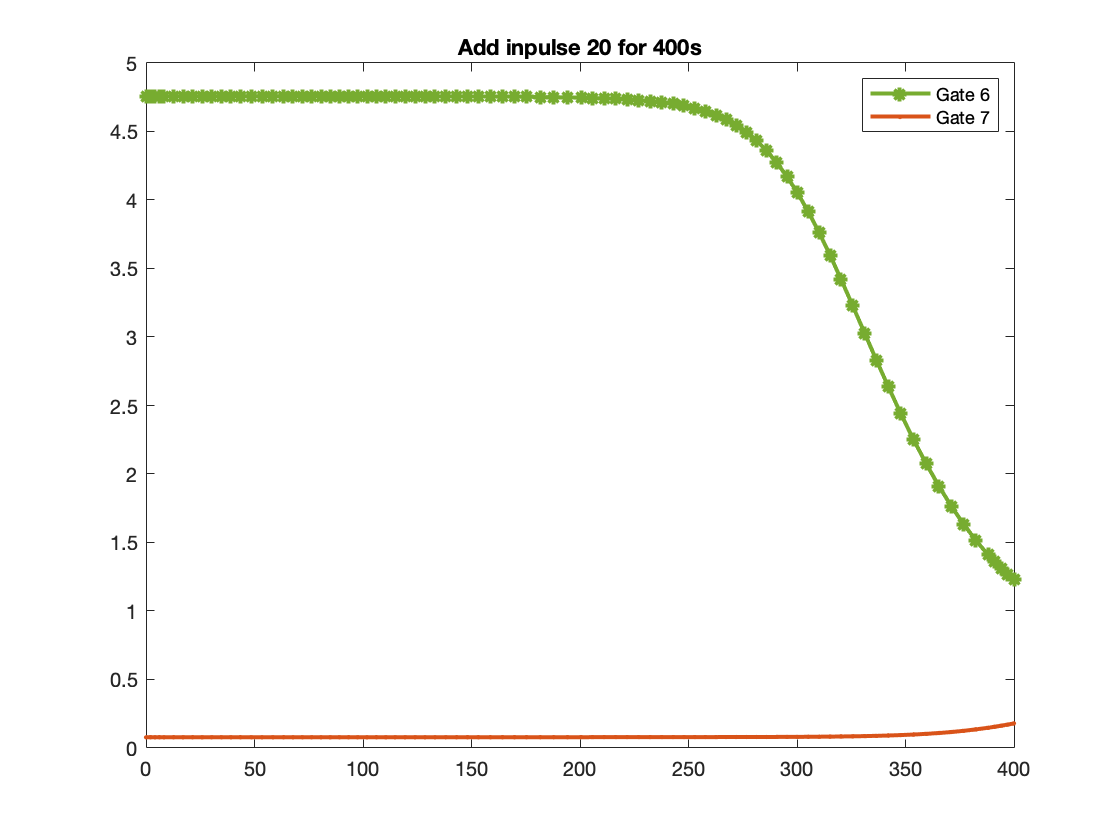

[t4,sol4] = ode45(@(t,x) plasmid(t,x,p),[0 400],u0_t3);
figure
plot(t4,sol4(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t4,sol4(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
title('Add inpulse 20 for 400s')

p4 = zeros(size(t4))+20

p4 =     20
    20
    20
    20
    20
    20
    20
    20
    20
    20



% 5. turn off p, p=0, for 570s
p = 0

p = 0

u0_t4 = sol4(end,:)

u0_t4 =     0.0701    0.2001    0.3218    0.0536    0.5171    1.2271    0.1792


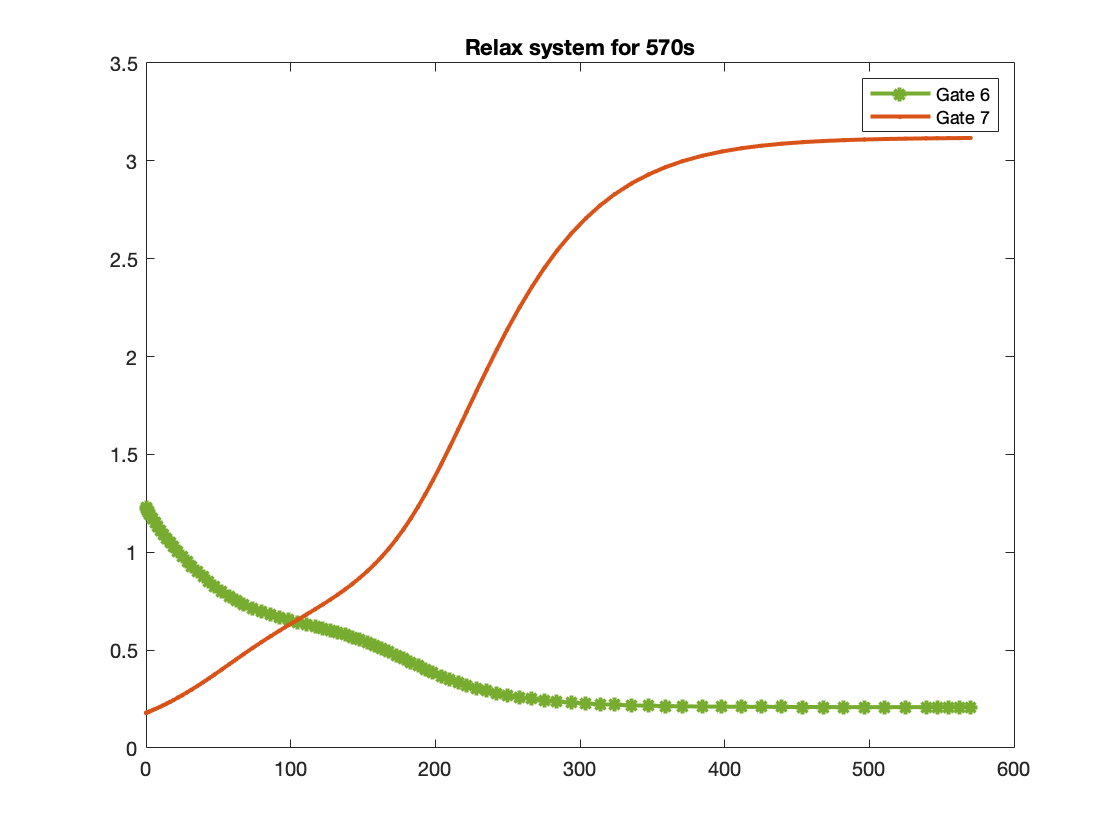

[t5,sol5] = ode45(@(t,x) plasmid(t,x,p),[0 570],u0_t4);
figure
plot(t5,sol5(:,6),'LineWidth',2,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on
plot(t5,sol5(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
legend('Gate 6','Gate 7')
title('Relax system for 570s')

p5 = zeros(size(t5))

p5 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% Final plot
P_set = [p1;p2;p3;p4;p5]

P_set =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



t2n = t2+t1(end)
t3n = t3 + t2(end) + t1(end)
t4n = t4 + t3(end) + t2(end) + t1(end)
t5n = t5 + t4(end) + t3(end) + t2(end) + t1(end)

t_set = [t1;t2n;t3n;t4n;t5n]

t_set = 	1.0e+03 *

         0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0163
    0.0245
    0.0327
    0.0409
    0.0486


sol_set =[sol1;sol2;sol3;sol4;sol5]

sol_set =     3.0000   16.0000    6.0000   13.0000   20.0000    9.0000   14.0000
    2.8564   15.2258    5.7062   12.3632   19.0201    8.5686   13.3172
    2.7198   14.4895    5.4268   11.7577   18.0882    8.1584   12.6678
    2.5899   13.7894    5.1612   11.1818   17.2020    7.7683   12.0503
    2.4664   13.1236    4.9085   10.6341   16.3592    7.3974   11.4630
    2.0208   10.7222    3.9972    8.6588   13.3194    6.0593    9.3447
    1.6582    8.7686    3.2554    7.0510   10.8453    4.9703    7.6207
    1.3638    7.1840    2.6531    5.7456    8.8363    4.0862    6.2210
    1.1241    5.8964    2.1628    4.6828    7.2009    3.3666    5.0817
    0.9401    4.9098    1.7863    3.8666    5.9448    2.8141    4.2068



figure
plot(t_set,sol_set(:,6),'LineWidth',1,"Marker","*","Color",'#77AC30','DisplayName','Gate6')
hold on;
plot(t_set,sol_set(:,7),'LineWidth',2,"Marker",".","Color",'#D95319','DisplayName','Gate7')
hold on;
plot(t_set, P_set,"-.",'LineWidth',2,"Color",'#7E2F8E')
legend('Gate 6','Gate 7')
ylim([0 22])
title('Circuit Simulation')
